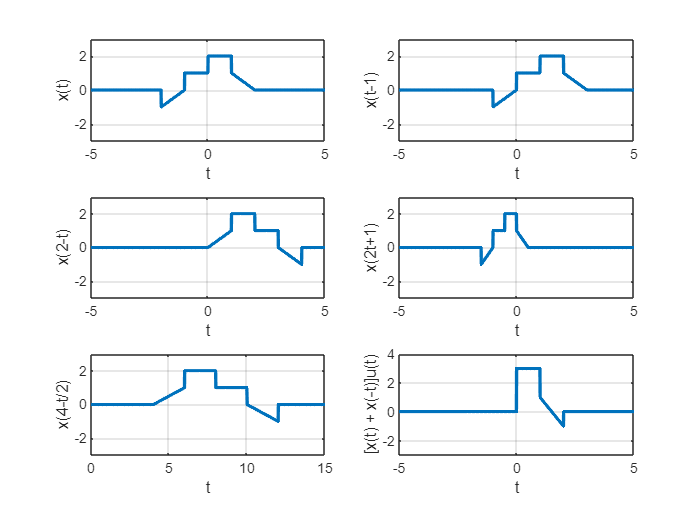

clear; clc; close all;

t = linspace(-5, 5, 1000);

u =@(t) 0.5*(sign(t) + 1);
x =@(t) (t+1).*(u(t+2)-u(t+1)) + (u(t+1)-u(t)) + 2.*(u(t)-u(t-1)) + (-t+2).*(u(t-1)-u(t-2));

figure(1);
subplot(3,2,1);
plot(t,x(t),"LineWidth",2);
ylim([-3,3]);
xlabel('t');
ylabel("x(t)");
grid on;

subplot(3,2,2);
plot(t,x(t-1),"LineWidth",2);
ylim([-3,3]);
xlabel('t');
ylabel("x(t-1)");
grid on;

subplot(3,2,3);
plot(t,x(2-t),"LineWidth",2);
ylim([-3,3]);
xlabel('t');
ylabel("x(2-t)");
grid on;

subplot(3,2,4);
plot(t,x(2*t+1),"LineWidth",2);
ylim([-3,3]);
xlabel('t');
ylabel("x(2t+1)");
grid on;

t2 = linspace(0,15,1000);

subplot(3,2,5);
plot(t2,x(4-(t2/2)),"LineWidth",2);
ylim([-3,3]);
xlabel('t');
ylabel("x(4-t/2)");
grid on;

subplot(3,2,6);
plot(t,(x(t) + x(-t)).*u(t),"LineWidth",2);
ylim([-3,4]);
xlabel('t');
ylabel("[x(t) + x(-t)]u(t)");
grid on;